# Wave Equation by Explicit Method

## 
$$\begin{array}{l}
u_{i,2} =\left(1-c^2 \lambda {\;}^2 \right)u_{i,1} +\frac{1}{2}c^2 \lambda {\;}^2 \cdot \left(u_{i+1,1} +u_{i-1,1} \right)+k\cdot g\left(x_i \right)\\
u_{i,j+1} =2\cdot \left(1-c^2 \lambda {\;}^2 \right)u_{i,j} +c^2 \lambda {\;}^2 \cdot \left(u_{i+1,j} +u_{i-1,j} \right)-u_{i,j-1} 
\end{array}$$


clear all;

% params
c = 2;

f = @(x) sin(pi*x);
g = @(x) 0;

h = 0.2;
k = 0.05;

tn = 0.1;
xn = 1;

% function
x = 0:h:xn;
t = 0:k:tn;

L = (k * c/ h)^2;

u = zeros(length(x), length(t));
u(:, 1) = f(x);

a=c*k/h;

for i = 2:length(x)-1
    u(i, 2) = (1-L)*u(i, 1) + 0.5*L*(u(i+1, 1) + u(i-1, 1)) + k*g(x(i));
    j = 2;
end

for j = 2:length(t)-1
    for i = 2:length(x)-1
        u(i, j+1) = 2*(1-L)*u(i,j ) + L * (u(i+1, j) + u(i-1, j)) - u(i,j-1);
    end
end


for j = 1:length(t)
    for i = 1:length(x)
        fprintf('value at u(%d, %d) is %f\n', i-1, j-1, u(i, j));
    end
    fprintf('\n');
end

value at u(0, 0) is 0.000000
value at u(1, 0) is 0.587785
value at u(2, 0) is 0.951057
value at u(3, 0) is 0.951057
value at u(4, 0) is 0.587785
value at u(5, 0) is 0.000000


value at u(0, 1) is 0.000000
value at u(1, 1) is 0.559721
value at u(2, 1) is 0.905648
value at u(3, 1) is 0.905648
value at u(4, 1) is 0.559721
value at u(5, 1) is 0.000000


value at u(0, 2) is 0.000000
value at u(1, 2) is 0.478208
value at u(2, 2) is 0.773757
value at u(3, 2) is 0.773757
value at u(4, 2) is 0.478208
value at u(5, 2) is 0.000000


disp(u)

         0         0         0
    0.5878    0.5597    0.4782
    0.9511    0.9056    0.7738
    0.9511    0.9056    0.7738
    0.5878    0.5597    0.4782
    0.0000         0         0



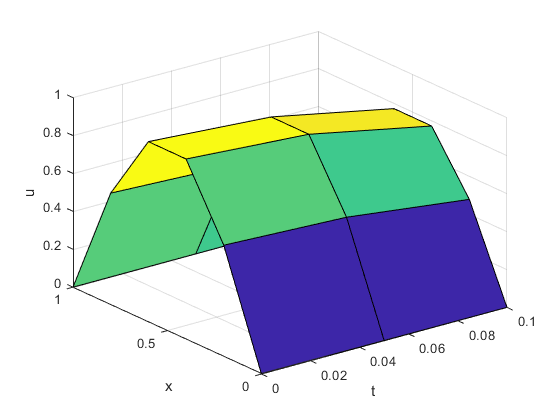

surf(t, x, u);
xlabel('t');
ylabel('x');
zlabel('u');